# -- DRAFT -- Basic Coding Examples for Class fockobj

*Matthias Wolff*

BTU Cottbus-Senftenberg

fock.addFockBoxPaths();

## 1  Simple Quantum States

**1.1   Preparation of a Simple Quantum State**

Get the basis vectors $|1\rangle$, $|2\rangle$, and $|3\rangle$ of a three-dimensional Fock sub-space:

b1 = fockobj.bket('1');
b2 = fockobj.bket('2');
b3 = fockobj.bket('3');

Prepare a quantum state 

        
$$|\varphi\rangle
= \sum\limits_{i=1}^3 \sqrt{p_i}\;|i\rangle$$
 

from probabilities $p_1$, $p_2$, and $p_3=1-p_1-p_2$:

p1 = 0.5;
p2 = 0.1;
p3 = 1-p1-p2;

phi = sqrt(p1)*b1 + sqrt(p2)*b2 + sqrt(p3)*b3; 

phi.name = '$|\varphi\rangle$';
disp(phi);

  fockobj

    Name: $|\varphi\rangle$ 
    Type: ket 

    (1,ε)               	0.707107
    (2,ε)               	0.316228
    (3,ε)               	0.632456


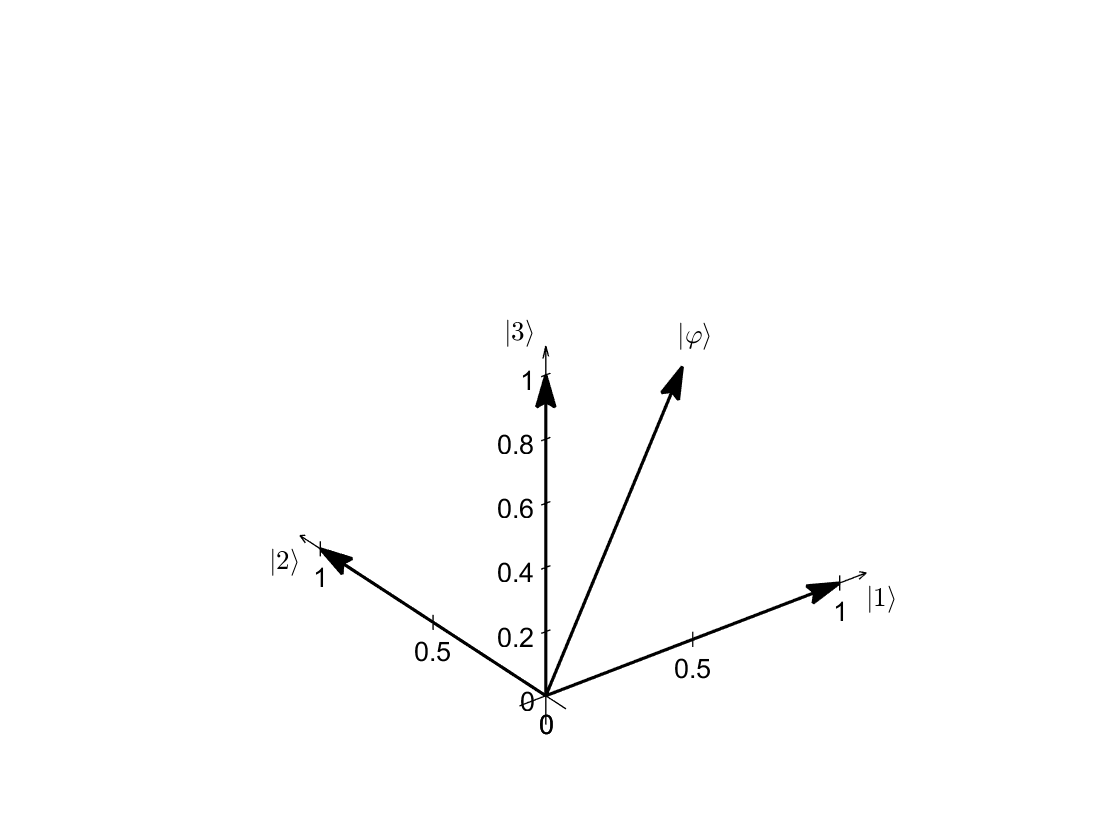

figure;
fock.plotVector({b1 b2 b3 phi},'axesLocation','origin');

$|\varphi\rangle$is a ket vector. Its (conjugate) transpose $\langle\varphi|=|\varphi\rangle^\dagger$ is a bra vector.

disp(phi');

  fockobj

    Name: $|\varphi\rangle$ 
    Type: bra 

    (ε,1)               	0.707107
    (ε,2)               	0.316228
    (ε,3)               	0.632456


**1.2   Projection and Measurement**

Create a projector 

        
$$P_{12}=|1\rangle\langle 1| + |2\rangle\langle 2|$$
 

onto the $|1\rangle$-$|2\rangle$sub-space

P12 = b1*b1' + b2*b2'; disp(P12);

  fockobj

    Type: linear operator 

    (1,1)               	1.000000
    (2,2)               	1.000000


and project $|\varphi\rangle$ onto that sub-space

        
$$\varphi_{12} = P_{12}\,|\varphi\rangle$$


phi12 = P12*phi; 

phi12.name = '$|\varphi_{12}\rangle$';
disp(phi12);

  fockobj

    Name: $|\varphi_{12}\rangle$ 
    Type: ket 

    (1,ε)               	0.707107
    (2,ε)               	0.316228


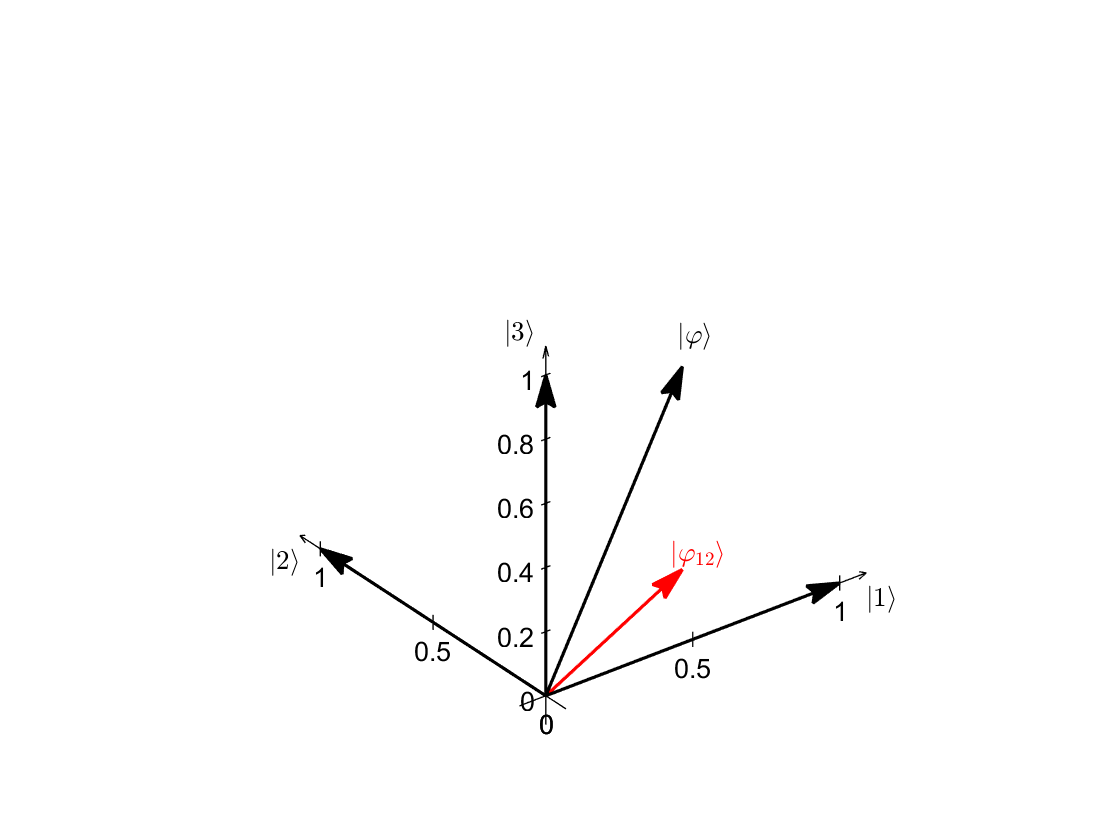

figure;
plt = fock.plotVector({b1 b2 b3 phi phi12},'axesLocation','origin');
fock.setVectorColor(plt.vec{5},'r');

The probability of the projection is

        
$$p_{12} = \langle\varphi|P_{12}|\varphi\rangle = p_1+p_2.$$


fprintf('p12 = %g',phi'*P12*phi);

p12 = 0.6

**1.3   State Evolution**

[**TODO**: ...]

## 2  Density Operators

[**TODO**: ...]

## 3  Quantum States in Fock Space

[**TODO**: ...]